f=@(x) cos(3*pi/2*x)

f = function_handle with value:
    @(x)cos(3*pi/2*x)


x=[0,1/2,1]

x =          0    0.5000    1.0000


%x=linspace(0,1,7)
xx=x(1):0.01:x(end);

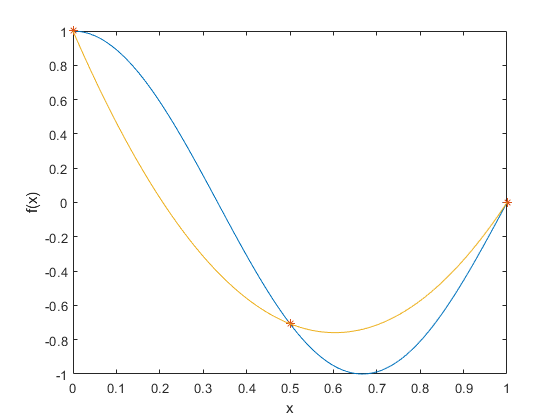

S1=spline(x,f(x));
plot(xx,f(xx),x,f(x),'*',xx,ppval(S1,xx))
xlabel('x') 
ylabel('f(x)') 

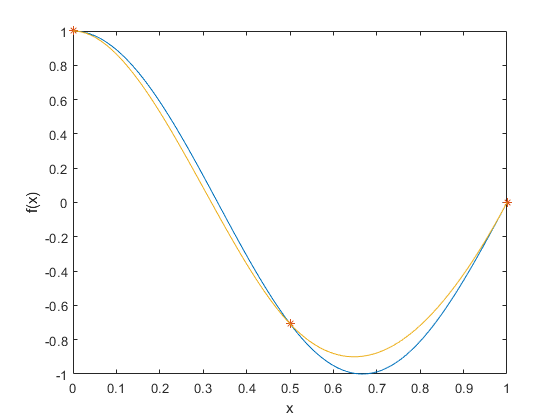

df=derivate(f);
S2=spline(x,[df(x(1)) f(x) df(x(end))]);
plot(xx,f(xx),x,f(x),'*',xx,ppval(S2,xx))
xlabel('x') 
ylabel('f(x)') 

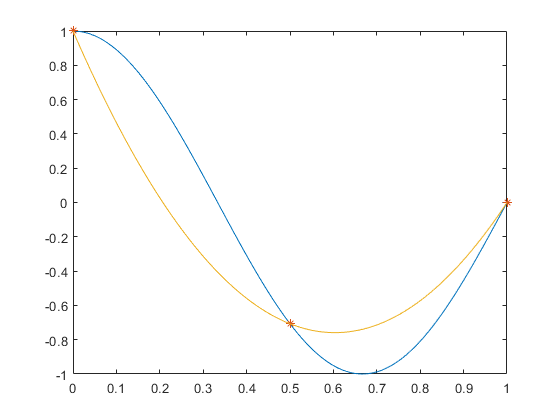

P=polyfit(x,f(x),length(x)-1);
plot(xx,f(xx),x,f(x),'*',xx,polyval(P,xx))

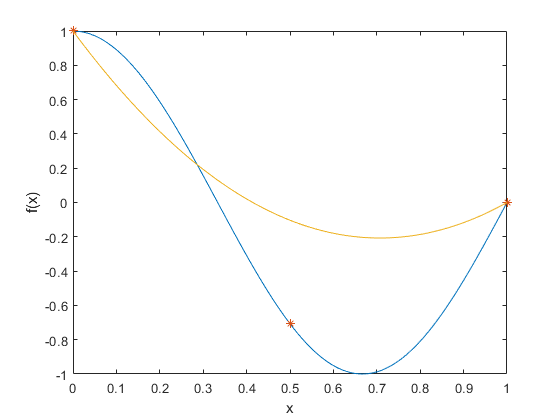

syms t
B=matlabFunction(bernstein(f,length(x)-1,t));
plot(xx,f(xx),x,f(x),'*',xx,B(xx))
xlabel('x') 
ylabel('f(x)') 